T_jets=parquetread('jets_train.parquet.gzip');

T_jets = movevars(T_jets,'is_signal_new','Before','E_0');
T_jets = sortrows(T_jets,'is_signal_new'); 
G = groupsummary(T_jets,'is_signal_new')

G = 2×2 table
    is_signal_new    GroupCount
    _____________    __________

          0            15068   
          1            14932   


T_jets.is_signal_new

ans = 30000×1 int64 column vector
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


Jet=Jet_Table_To_Jet_Tensor(T_jets);
pT=sqrt(Jet(:,2,:).^2+Jet(:,3,:).^2);         % transverse momentum of jet constituents
eta=squeeze(asinh(Jet(:,4,:)./pT));           % pseudorapidity tensor eta with 35 rows and 30k columns
phi=squeeze(atan2(Jet(:,3,:),Jet(:,2,:)));    % azimuth tensor phi with 35 rows and 30k columns

JetLabels

eta = eta - eta(1,:);        % this and line below: centering the hardest jet constituent in (eta,phi) grid
phi = phi - phi(1,:);        % jet constituent with the largest pT will have eta=phi=0  

Nb=37;                                 % number of buckets for eta and phi  
Xedges=linspace(-1.6,1.6,Nb+1);        % edges for buckets for eta. Nb+1 edges means Nb buckets 
Yedges=linspace(-1.6,1.6,Nb+1); 

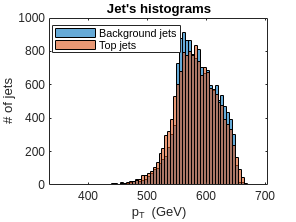

P=squeeze(sum(pT,1));                  % total transverse momentum of a jet
clf;
histogram(P(1:G{1,2}));                % distribution of transverse momenta of background jets
hold on
histogram(P(G{1,2}+1:end));            % distribution of transverse momenta of top jets
title("Jet's histograms")
legend({'Background jets','Top jets'},'Location','best')
xlabel("p_T (GeV)")
ylabel("# of jets")
hold off

xGrp = discretize(eta,Xedges);    % xGrp is same size as eta: 35x30k. Instead of eta values, xGrp contains bucket numbers for that values of eta
yGrp = discretize(phi,Yedges);    % yGrp is same size as phi: 35x30k. Instead of phi values, yGrp contains bucket numbers for that value of phi
zGrp = repelem(1:size(Jet,3),size(eta,1));       % zGrp is a row vector with 35*30k elements: 1,1,1..., 2,2,2..., 30k,30k,30k... 
V = rmmissing([pT(:) xGrp(:) yGrp(:) zGrp(:)]);  % remove rows with missing entries from a matrix V with 4 columns 
I = accumarray(V(:,2:4), V(:,1), [Nb, Nb, size(Jet,3)]);

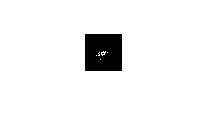

imshow(I(:,:,1))

imwrite(I(:,:,1),"sample.png");

Ia=zeros(Nb^2,size(Jet,3));
parfor n=1:size(Jet,3)
    Ia(:,n)=reshape(I(:,:,n),Nb^2,1);
    Ia(:,n)=circshift(Ia(:,n),ceil(length(Ia(:,n))/2)-find(Ia(:,n)==max(Ia(:,n)))); % maximum of I will be centered       
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 2 workers.


Ia=normalize(Ia,'norm');            % normalize each column of Ia
I=reshape(Ia,Nb,Nb,[]);

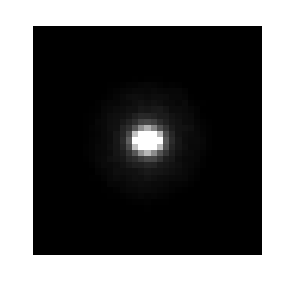

I_b=sum(I(:,:,1:G{1,2}),3)/200;      % sum all background jets
I_t=sum(I(:,:,G{1,2}+1:end),3)/200;  % sum all top jets
imshow(I_b)
truesize([300, 300]) 

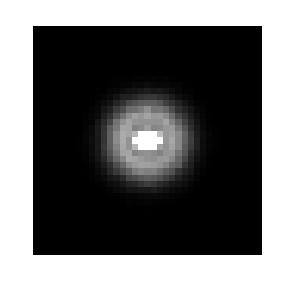

imshow(I_t)
truesize([300, 300]) 

imshow(I(:,:,1))

imwrite(I(:,:,1),"example.png");

sz=size(I);
nsamples = sz(3)

nsamples = 30000

tab = table;
for i=1:nsamples
  mat = I(:,:,i);
  nonzero_rows = single([]);
  nonzero_cols = single([]);
  track_pt = single([]);
  for r=1:37
    for c=1:37
      has_nonzero = false;
      for k=1:1
        if mat(r,c,k) > 0.001
          has_nonzero = true;
        end
      end
      if has_nonzero
        nonzero_rows = [nonzero_rows; r];
        nonzero_cols = [nonzero_cols; c];
        track_pt = [track_pt; mat(r,c,1)];
      end
    end
  end
  row = nonzero_rows;
  col = nonzero_cols;  
   
  kvalue = 3;
  knns = knnsearch([row,col],[row,col],'K',kvalue+1,'Distance','Euclidean');
  A = zeros(length(knns));
  if length(knns) <= kvalue
    continue;
  end
  for n=1:length(knns)
    for m=2:kvalue+1
      A(knns(n,1),knns(n,m)) = 1;
    end
  end
  A = A + eye(size(A));
  g = digraph(A);
  
  clear newtab;
  newtab = table;
  newtab.coords0 = {(nonzero_rows - 63)/62};
  newtab.coords1 = {(nonzero_cols - 63)/62};
  newtab.edge_index_from = {int64(g.Edges.EndNodes(:,2)-1)};
  newtab.edge_index_to = {int64(g.Edges.EndNodes(:,1)-1)};
  newtab.pT = {track_pt};
  newtab.y = T_jets.is_signal_new(i);

  tab = [tab; newtab];
end


save("../data/train_graphs.mat","tab")

train_graphs = tab

train_graphs = 29943×6 table
       coords0          coords1       edge_index_from    edge_index_to         pT          y
    _____________    _____________    _______________    _____________    _____________    _

    {22×1 single}    {22×1 single}     { 88×1 int64}     { 88×1 int64}    {22×1 single}    0
    {19×1 single}    {19×1 single}     { 76×1 int64}     { 76×1 int64}    {19×1 single}    0
    {20×1 single}    {20×1 single}     { 80×1 int64}     { 80×1 int64}    {20×1 single}    0
    {17×1 single}    {17×1 single}     { 68×1 int64}     { 68×1 int64}    {17×1 single}    0
    {17×1 single}    {17×1 single}     { 68×1 int64}     { 68×1 int64}    {17×1 single}    0
    {15×1 single}    {15×1 single}     { 60×1 int64}     { 60×1 int64}    {15×1 single}    0
    {28×1 single}    {

rowgroupheights = ones([1 3200])

rowgroupheights =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


pq1 = train_graphs(1:3200,:)

pq1 = 3200×6 table
       coords0          coords1       edge_index_from    edge_index_to         pT          y
    _____________    _____________    _______________    _____________    _____________    _

    {22×1 single}    {22×1 single}     { 88×1 int64}     { 88×1 int64}    {22×1 single}    0
    {19×1 single}    {19×1 single}     { 76×1 int64}     { 76×1 int64}    {19×1 single}    0
    {20×1 single}    {20×1 single}     { 80×1 int64}     { 80×1 int64}    {20×1 single}    0
    {17×1 single}    {17×1 single}     { 68×1 int64}     { 68×1 int64}    {17×1 single}    0
    {17×1 single}    {17×1 single}     { 68×1 int64}     { 68×1 int64}    {17×1 single}    0
    {15×1 single}    {15×1 single}     { 60×1 int64}     { 60×1 int64}    {15×1 single}    0
    {28×1 single}    {28×1 singl

pq2 = train_graphs(3201:6400,:)

pq2 = 3200×6 table
       coords0          coords1       edge_index_from    edge_index_to         pT          y
    _____________    _____________    _______________    _____________    _____________    _

    {17×1 single}    {17×1 single}     {68×1 int64}      {68×1 int64}     {17×1 single}    0
    {24×1 single}    {24×1 single}     {96×1 int64}      {96×1 int64}     {24×1 single}    0
    {21×1 single}    {21×1 single}     {84×1 int64}      {84×1 int64}     {21×1 single}    0
    {15×1 single}    {15×1 single}     {60×1 int64}      {60×1 int64}     {15×1 single}    0
    {23×1 single}    {23×1 single}     {92×1 int64}      {92×1 int64}     {23×1 single}    0
    {16×1 single}    {16×1 single}     {64×1 int64}      {64×1 int64}     {16×1 single}    0
    {20×1 single}    {20×1 singl

pq3 = train_graphs(6401:9600,:)

pq3 = 3200×6 table
       coords0          coords1       edge_index_from    edge_index_to         pT          y
    _____________    _____________    _______________    _____________    _____________    _

    {25×1 single}    {25×1 single}     {100×1 int64}     {100×1 int64}    {25×1 single}    0
    {12×1 single}    {12×1 single}     { 48×1 int64}     { 48×1 int64}    {12×1 single}    0
    {17×1 single}    {17×1 single}     { 68×1 int64}     { 68×1 int64}    {17×1 single}    0
    {17×1 single}    {17×1 single}     { 68×1 int64}     { 68×1 int64}    {17×1 single}    0
    {16×1 single}    {16×1 single}     { 64×1 int64}     { 64×1 int64}    {16×1 single}    0
    {11×1 single}    {11×1 single}     { 44×1 int64}     { 44×1 int64}    {11×1 single}    0
    {13×1 single}    {13×1 singl

pq4 = train_graphs(9601:12800,:)

pq4 = 3200×6 table
       coords0          coords1       edge_index_from    edge_index_to         pT          y
    _____________    _____________    _______________    _____________    _____________    _

    {25×1 single}    {25×1 single}     {100×1 int64}     {100×1 int64}    {25×1 single}    0
    {17×1 single}    {17×1 single}     { 68×1 int64}     { 68×1 int64}    {17×1 single}    0
    {18×1 single}    {18×1 single}     { 72×1 int64}     { 72×1 int64}    {18×1 single}    0
    {21×1 single}    {21×1 single}     { 84×1 int64}     { 84×1 int64}    {21×1 single}    0
    {21×1 single}    {21×1 single}     { 84×1 int64}     { 84×1 int64}    {21×1 single}    0
    {17×1 single}    {17×1 single}     { 68×1 int64}     { 68×1 int64}    {17×1 single}    0
    { 8×1 single}    { 8×1 singl

pq5 = train_graphs(12801:16000,:)

pq5 = 3200×6 table
       coords0          coords1       edge_index_from    edge_index_to         pT          y
    _____________    _____________    _______________    _____________    _____________    _

    {24×1 single}    {24×1 single}     { 96×1 int64}     { 96×1 int64}    {24×1 single}    0
    {15×1 single}    {15×1 single}     { 60×1 int64}     { 60×1 int64}    {15×1 single}    0
    {11×1 single}    {11×1 single}     { 44×1 int64}     { 44×1 int64}    {11×1 single}    0
    {18×1 single}    {18×1 single}     { 72×1 int64}     { 72×1 int64}    {18×1 single}    0
    {18×1 single}    {18×1 single}     { 72×1 int64}     { 72×1 int64}    {18×1 single}    0
    {15×1 single}    {15×1 single}     { 60×1 int64}     { 60×1 int64}    {15×1 single}    0
    {24×1 single}    {24×1 singl

pq6 = train_graphs(16001:19200,:)

pq6 = 3200×6 table
       coords0          coords1       edge_index_from    edge_index_to         pT          y
    _____________    _____________    _______________    _____________    _____________    _

    {12×1 single}    {12×1 single}     { 48×1 int64}     { 48×1 int64}    {12×1 single}    1
    {22×1 single}    {22×1 single}     { 88×1 int64}     { 88×1 int64}    {22×1 single}    1
    {10×1 single}    {10×1 single}     { 40×1 int64}     { 40×1 int64}    {10×1 single}    1
    {17×1 single}    {17×1 single}     { 68×1 int64}     { 68×1 int64}    {17×1 single}    1
    {18×1 single}    {18×1 single}     { 72×1 int64}     { 72×1 int64}    {18×1 single}    1
    {11×1 single}    {11×1 single}     { 44×1 int64}     { 44×1 int64}    {11×1 single}    1
    {16×1 single}    {16×1 singl

pq7 = train_graphs(19201:22400,:)

pq7 = 3200×6 table
       coords0          coords1       edge_index_from    edge_index_to         pT          y
    _____________    _____________    _______________    _____________    _____________    _

    {24×1 single}    {24×1 single}     { 96×1 int64}     { 96×1 int64}    {24×1 single}    1
    {25×1 single}    {25×1 single}     {100×1 int64}     {100×1 int64}    {25×1 single}    1
    {22×1 single}    {22×1 single}     { 88×1 int64}     { 88×1 int64}    {22×1 single}    1
    {21×1 single}    {21×1 single}     { 84×1 int64}     { 84×1 int64}    {21×1 single}    1
    { 9×1 single}    { 9×1 single}     { 36×1 int64}     { 36×1 int64}    { 9×1 single}    1
    {16×1 single}    {16×1 single}     { 64×1 int64}     { 64×1 int64}    {16×1 single}    1
    {24×1 single}    {24×1 singl

pq8 = train_graphs(22401:25600,:)

pq8 = 3200×6 table
       coords0          coords1       edge_index_from    edge_index_to         pT          y
    _____________    _____________    _______________    _____________    _____________    _

    {10×1 single}    {10×1 single}     { 40×1 int64}     { 40×1 int64}    {10×1 single}    1
    {25×1 single}    {25×1 single}     {100×1 int64}     {100×1 int64}    {25×1 single}    1
    {25×1 single}    {25×1 single}     {100×1 int64}     {100×1 int64}    {25×1 single}    1
    {15×1 single}    {15×1 single}     { 60×1 int64}     { 60×1 int64}    {15×1 single}    1
    {20×1 single}    {20×1 single}     { 80×1 int64}     { 80×1 int64}    {20×1 single}    1
    {16×1 single}    {16×1 single}     { 64×1 int64}     { 64×1 int64}    {16×1 single}    1
    {20×1 single}    {20×1 singl

pq9 = train_graphs(25601:28800,:)

pq9 = 3200×6 table
       coords0          coords1       edge_index_from    edge_index_to         pT          y
    _____________    _____________    _______________    _____________    _____________    _

    {25×1 single}    {25×1 single}     {100×1 int64}     {100×1 int64}    {25×1 single}    1
    {24×1 single}    {24×1 single}     { 96×1 int64}     { 96×1 int64}    {24×1 single}    1
    {21×1 single}    {21×1 single}     { 84×1 int64}     { 84×1 int64}    {21×1 single}    1
    {19×1 single}    {19×1 single}     { 76×1 int64}     { 76×1 int64}    {19×1 single}    1
    {25×1 single}    {25×1 single}     {100×1 int64}     {100×1 int64}    {25×1 single}    1
    {23×1 single}    {23×1 single}     { 92×1 int64}     { 92×1 int64}    {23×1 single}    1
    {23×1 single}    {23×1 singl

pq10 = train_graphs(28801:29943,:)

pq10 = 1143×6 table
       coords0          coords1       edge_index_from    edge_index_to         pT          y
    _____________    _____________    _______________    _____________    _____________    _

    {14×1 single}    {14×1 single}     { 56×1 int64}     { 56×1 int64}    {14×1 single}    1
    {15×1 single}    {15×1 single}     { 60×1 int64}     { 60×1 int64}    {15×1 single}    1
    {19×1 single}    {19×1 single}     { 76×1 int64}     { 76×1 int64}    {19×1 single}    1
    {18×1 single}    {18×1 single}     { 72×1 int64}     { 72×1 int64}    {18×1 single}    1
    {18×1 single}    {18×1 single}     { 72×1 int64}     { 72×1 int64}    {18×1 single}    1
    {18×1 single}    {18×1 single}     { 72×1 int64}     { 72×1 int64}    {18×1 single}    1
    {25×1 single}    {25×1 sing

parquetwrite("train_zenodo_1.parquet",pq1,"RowGroupHeights",rowgroupheights)
parquetwrite("train_zenodo_2.parquet",pq2,"RowGroupHeights",rowgroupheights)
parquetwrite("train_zenodo_3.parquet",pq3,"RowGroupHeights",rowgroupheights)
parquetwrite("train_zenodo_4.parquet",pq4,"RowGroupHeights",rowgroupheights)
parquetwrite("train_zenodo_5.parquet",pq5,"RowGroupHeights",rowgroupheights)
parquetwrite("train_zenodo_6.parquet",pq6,"RowGroupHeights",rowgroupheights)
parquetwrite("train_zenodo_7.parquet",pq7,"RowGroupHeights",rowgroupheights)
parquetwrite("train_zenodo_8.parquet",pq8,"RowGroupHeights",rowgroupheights)
parquetwrite("train_zenodo_9.parquet",pq9,"RowGroupHeights",rowgroupheights)
parquetwrite("train_zenodo_10.parquet",pq10,"RowGroupHeights",ones([1 1143]))

index = 1;
adj = cell2mat(table2array(t(index,"Adjacency")));
feats = cell2mat(table2array(t(index,"Features")));
g1 = digraph(adj);
plot(g1,"NodeLabel",feats)

MATLAB has experienced a low-level graphics error, and may not have drawn correctly.
Read about what you can do to prevent this issue at Resolving Low-Level Graphics Issues then restart MATLAB.
To share details of this issue with MathWorks technical support,
please include <a href="file:/home/colin/jogl.ex.4990">this file</a> with your service request.



x0=10;
y0=10;
width=600;
height=600
set(gcf,'position',[x0,y0,width,height])

function y= Jet_Table_To_Jet_Tensor(x)
    y = x{:,2:4*35+1}';                
    y = reshape(y,4,35,[]);              
    y = pagetranspose(y);
end